c = 340;                    % Sound velocity (m/s)
fs = 16000;                 % Sample frequency (samples/s)
mic_loc = [2 1.5 2];              % Receiver position [x y z] (m)
src_loc = [2 3.5 2];              % Source position [x y z] (m)
room_dim = [5 4 6];                % Room dimensions [x y z] (m)
num_samples = 2048;                   % Number of samples
reverb = 0.2 + 0.6*rand();                 % Reverberation time (s)
mtype = 'spherical';    % Type of microphone
order = -1;                 % -1 equals maximum reflection order!
dim = 3;                    % Room dimension
orientation1 = [atan(1/sqrt(2)) pi/4];
orientation2 = [-atan(1/sqrt(2)) 3*pi/4];
orientation3 = [atan(1/sqrt(2)) -3*pi/4];
orientation4 = [-atan(1/sqrt(2)) -pi/4]; % Microphone orientation (rad)
hp_filter = 0;              % Disable high-pass filter

responses = zeros(4,num_samples);
responses(1, :) = rir_generator(c, fs, mic_loc, src_loc, room_dim, reverb, num_samples, mtype, order, dim, orientation1, hp_filter);

Room Impulse Response Generator (Version 2.2.20201022) by Emanuel Habets
Copyright (C) 2003-2020 E.A.P. Habets


responses(2, :) = rir_generator(c, fs, mic_loc, src_loc, room_dim, reverb, num_samples, mtype, order, dim, orientation2, hp_filter);

Room Impulse Response Generator (Version 2.2.20201022) by Emanuel Habets
Copyright (C) 2003-2020 E.A.P. Habets


responses(3, :) = rir_generator(c, fs, mic_loc, src_loc, room_dim, reverb, num_samples, mtype, order, dim, orientation3, hp_filter);

Room Impulse Response Generator (Version 2.2.20201022) by Emanuel Habets
Copyright (C) 2003-2020 E.A.P. Habets


responses(4, :) = rir_generator(c, fs, mic_loc, src_loc, room_dim, reverb, num_samples, mtype, order, dim, orientation4, hp_filter);

Room Impulse Response Generator (Version 2.2.20201022) by Emanuel Habets
Copyright (C) 2003-2020 E.A.P. Habets


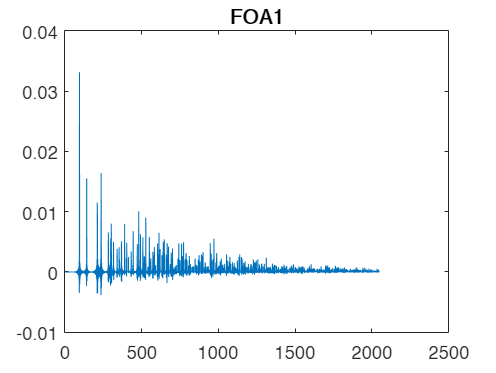

plot(responses(1, :));
title('FOA1');

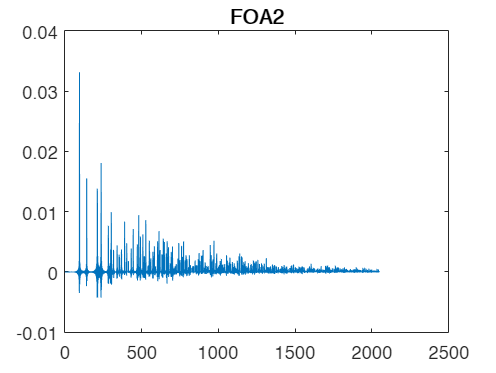

plot(responses(2, :));
title('FOA2');

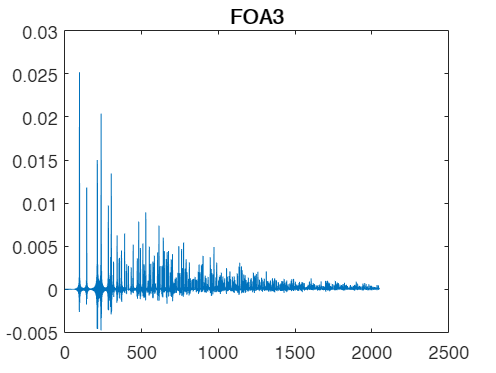

plot(responses(3, :));
title('FOA3');

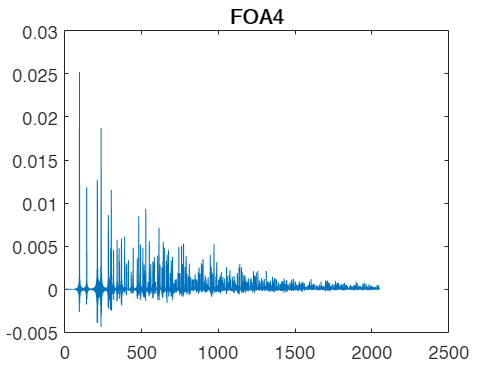

plot(responses(4, :));
title('FOA4');

save('foa1.mat', "responses", "mic_loc", "src_loc", "num_samples", "reverb", "room_dim")

Z = responses(1, :) - responses(2, :) + responses(3, :) - responses(4, :);
X = responses(1, :) - responses(2, :) - responses(3, :) + responses(4, :);

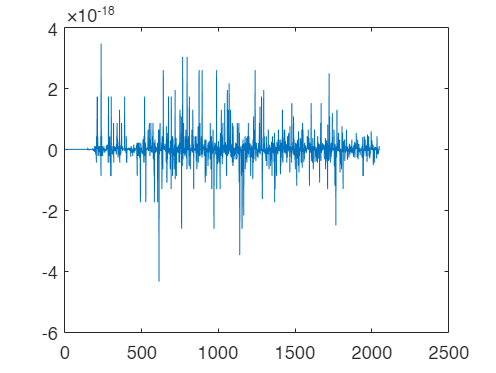

plot(Z)

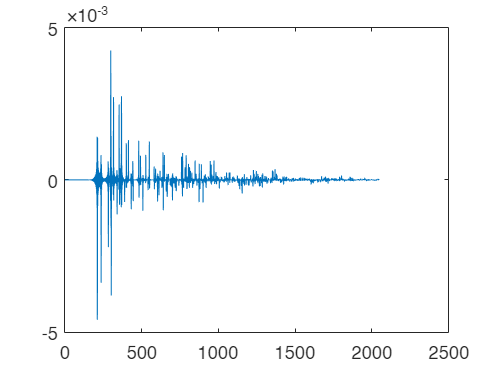

plot(X)

[y, fs] = audioread("sample.flac");
fs

fs = 16000

result = conv(y, X);
player = audioplayer(result, fs);
player.play();